clear all;

## Onset Conditions

dimension:

N=1500;
% correlation paramter:
eta=1;% 1 is symmetric
% amplitude
JAmp=1;
% Sparsity of J
Mdensity=0;
% Tot time 
tot_time=5000;
% Delta t:
Dt=0.1;
% Temperature: Increase it!!!
T=0.01;
% Initialise
J=zeros(N,N);
%x=zeros(N,N_tot);
% ICs
var_ICs_X=0.01;
x(:,1)=var_ICs_X*randn(N,1);
M=sum(x(:,1).^2);
% Fix the constraint sum x^2=N for all t
x(:,1)=x(:,1)*sqrt(N)/sqrt(M);

## Generate Random Matrix:

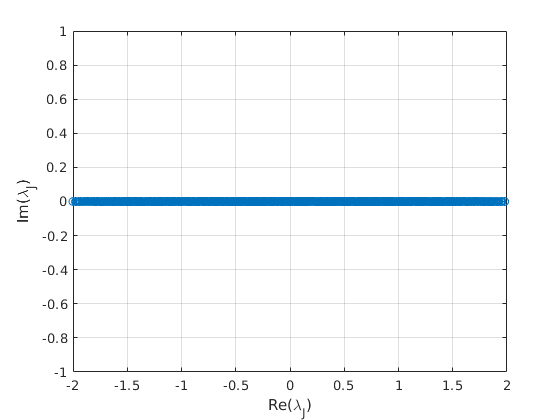

if eta==0
    J=JAmp/sqrt(N)*randn(N);   
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
J=J-diag(diag(J));
else
    a=sqrt(1-eta^2);
    a=sqrt((1-a)/2);
    b=eta/(2*a);    
    J=JAmp/sqrt(N)*randn(N);    
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
    J=a*J+b*J';
    J=J-diag(diag(J));
end;
figure;
plot(real(eig(J)),imag(eig(J)),'o');hold on;grid on;
xlabel('Re(\lambda_J)');
ylabel('Im(\lambda_J)')

%hold on;

## Run Dynamics

N_iter=tot_time/Dt;
tic
for i=2:N_iter
        z=randn(N,1)*sqrt(2*Dt*T);
        f=Dt*J*x(:,i-1)+z;
        x_norm=norm(x(:,i-1))^2;
        %x_norm=N;
        xf=x(:,i-1)'*f;
        x(:,i)=x(:,i-1)*(-xf/x_norm+sqrt((xf/x_norm)^2+(N-norm(f)^2)/x_norm))+f;
end
toc

Elapsed time is 366.201530 seconds.


save('low_T_unperturbed','x','J','T','Dt','tot_time');

load('low_T_unperturbed.mat')

## Perturned Dynamics   $ $\frac{x_{per}-x_{unp}}{h}=\int_0^{t} dt' G(t')$$

unper=perturbed(x(:,end),T,100,0.001,N,J,0);

Elapsed time is 13.027254 seconds.


h =           0.1


Elapsed time is 14.029554 seconds.


       1.0077



h =          0.01


Elapsed time is 14.302537 seconds.


        0.952



h =         0.001


Elapsed time is 14.297968 seconds.


       0.9596



h =        0.0001


Elapsed time is 13.710655 seconds.


      -4.8755



ans =       0.73616


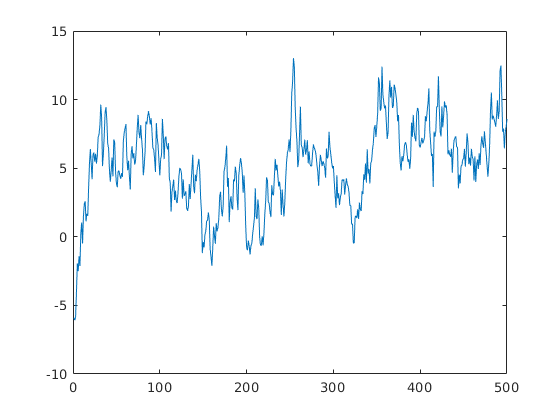

for i=1:4
    h=10^(-i)
    per=perturbed(x(:,end),T,100,0.001,N,J,h);
    disp((per-unper)/h)
end

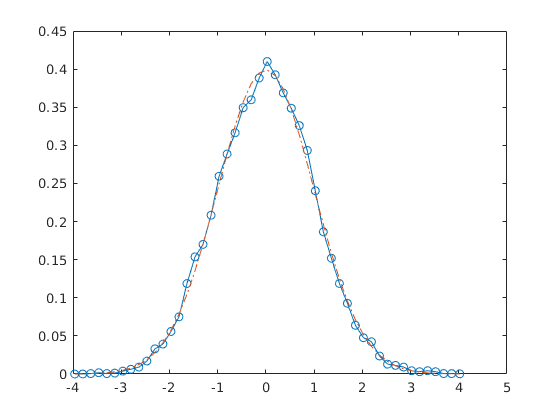

figure()
%histogram of position for one spin
bin_edge=linspace(min(x(:)),max(x(:)),50);
H=0;
for i=1:size(x,1)
    [h,b]=histcounts(x(:,i),bin_edge);
    H=H+h;
end
normalisation=sum(H)*(bin_edge(2)-bin_edge(1));
plot((bin_edge(1:end-1)+bin_edge(2:end))/2,H/normalisation,'-o')
hold on
spins=(bin_edge(1:end-1)+bin_edge(2:end))/2;
prob=exp(-spins.^2/2);
plot(spins,prob/sum(prob)/(bin_edge(2)-bin_edge(1)),'-.')

I compute  $\langle x_t x_{t'}\rangle=\frac{1}{N}\sum_{i=1}^N x_{i,t}x_{i,t'}$ i.e. I average over the different realisation of the spins.

% this is the fastest way to compute the correlation function
figure()
%t_wait=N^(2/3)/(1-T);
t_wait=3500;
y=x(:,round(t_wait/Dt):end);% wait for thermalisation
t=round(size(y,2)/2);% this is the maximum time to observe a correlation
clear corr;
for i=1:size(y,1)
    corr(i,:)=xcorr(y(i,:),t,'unbiased');
end
corr=corr(:,ceil(end/2):end);


Plot the correlation function

mean_corr=mean(corr,1);
std_corr=std(corr,1);
plot((1:length(corr))*Dt,mean_corr,'LineWidth',3,'DisplayName','Correlation')
xlim([0,500]);
hold on
plot([0,500],[1-T,1-T],'--','LineWidth',3,'DisplayName','q=1-T')
f=fill([(1:length(corr))*Dt fliplr((1:length(corr))*Dt)],[mean_corr-std_corr/N  fliplr(mean_corr+std_corr/N)],'g','DisplayName','Std. deviation')

f =   Patch (Std. deviation) with properties:

    FaceColor: [0 1 0]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [1×15004 double]
     Vertices: [15004×2 double]

  Show all properties


set(f,'facealpha',.25)
hold off
lg=legend('show')

lg =   Legend (Correlation, q=1-T, Std. deviation) with properties:

         String: {'Correlation'  'q=1-T'  'Std. deviation'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.69211 0.8178 0.25763 0.12594]
          Units: 'normalized'

  Show all properties


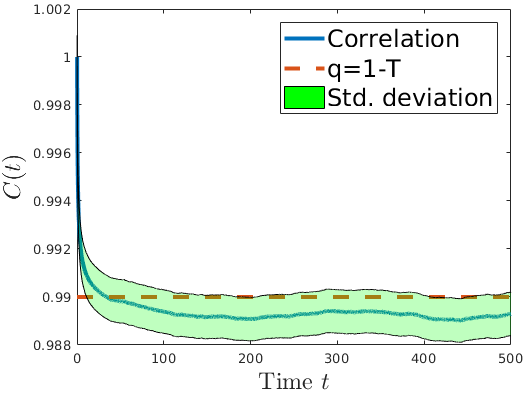

ans =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [403 246 524.13 396.8]
       Units: 'pixels'

  Show all properties


lg.FontSize=18;
xlabel('Time $t$','Interpreter','latex','FontSize',18)
ylabel('$C(t)$','Interpreter','latex','FontSize',18)
tightfig()

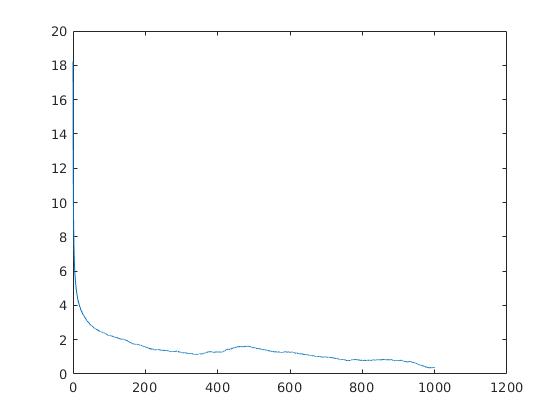

plot((1:length(cov))*Dt,cov)

% Fourier transfrorm of correlation function
P2=abs(fft(corr));
P1=P2(1:(end+1)/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = 1/Dt*linspace(0,0.5,N_iter);
plot(f,P1(1:end-2))

Error using plot
Vectors must be the same length.

q vs temperature

for i=1:9
    i
    trajectory=steps(x(:,1),0.1*i,100000,Dt,N,J,0);
    q(i)=EA_parameter(trajectory,Dt);
end

i =      1


Elapsed time is 124.575400 seconds.


q =       0.88244


i =      2


Elapsed time is 134.223360 seconds.


q =       0.71717


i =      3


Elapsed time is 125.298305 seconds.


q =       0.64678


i =      4


Elapsed time is 126.464089 seconds.


q =        0.5267


i =      5


Elapsed time is 125.761424 seconds.


q =       0.25847


i =      6


Elapsed time is 125.598409 seconds.


q =       0.12418


i =      7


Elapsed time is 125.832352 seconds.


q =     -0.091781


i =      8


Elapsed time is 125.657601 seconds.


q =      0.080224


i =      9


Elapsed time is 125.800408 seconds.


q =     -0.015756


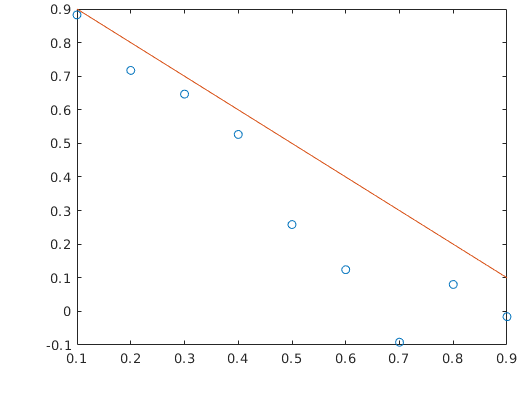

plot((1:9)*0.1,q,'o')
hold on
plot((1:9)*0.1,1-(1:9)*0.1)
hold off

%Integrated response function
load('perturbed_low_T.mat')
pert=x;
clear x
load('low_T.mat');
unpert=x;

mean((mean(pert))-mean(mean(unpert)))./0.001

ans =       0.90967
